## Lecture 1

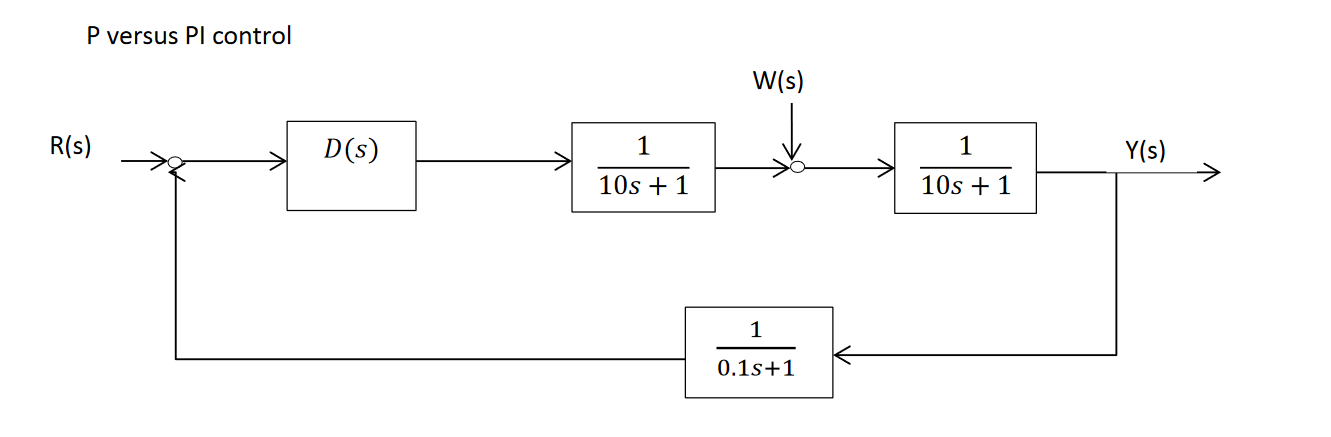

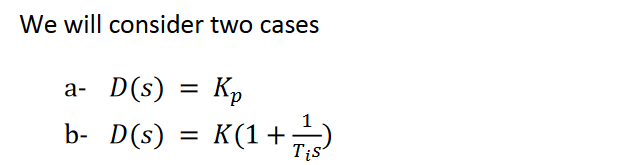

#### 1)

syms s Kt
Kp = 7.3;
G = 1/(10*s+1);
K = 1/(0.1*s + 1);
H1 = ((Kp*G*G)/(1+(G*G*K))); %closed loop
H2 = G*G*K

$$H2 = \frac{1}{{\left(10\,s+1\right)}^{2}\,\left(\frac{s}{10}+1\right)}$$

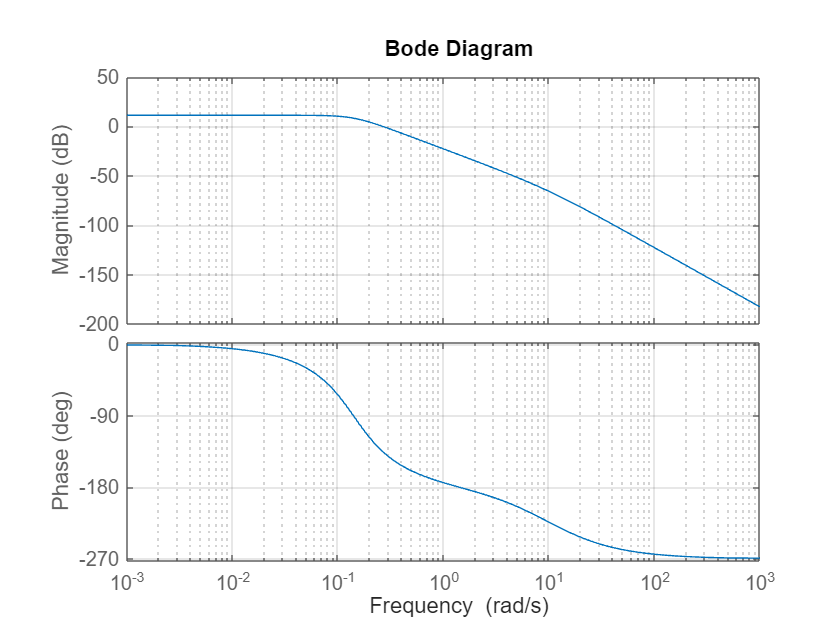

collect(H2);
% collect(H,s);
sys = tf([Kp*10],[100 1020 201 20]);
bodeplot(sys)
grid on;

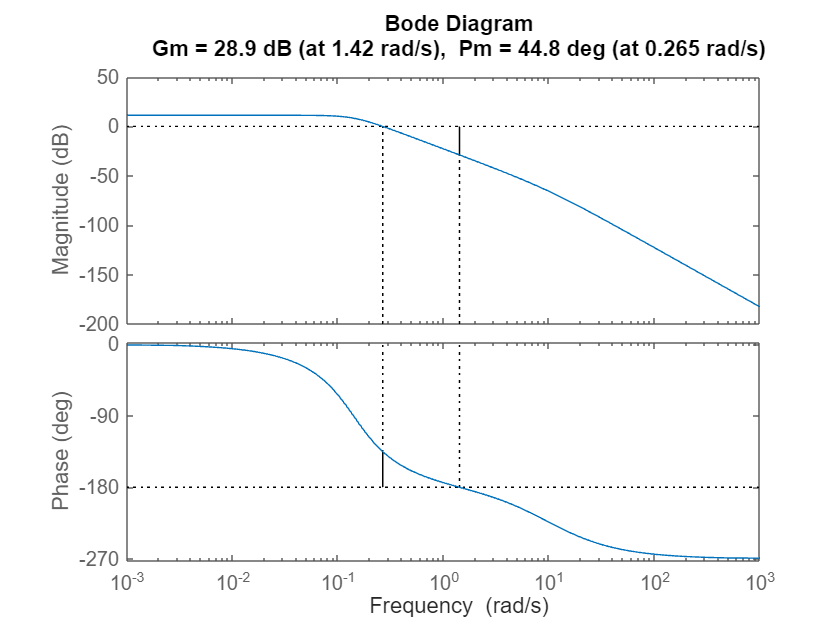

margin(sys); %sæt kp til 7.3 for cirka 45 PM

syms X;
vpa(solve(17==20*log10(X)));
collect(0.1/((s+0.1)*(s+10)*s),s)

$$ans = \frac{1}{10\,s^{3}+101\,s^{2}+10\,s}$$

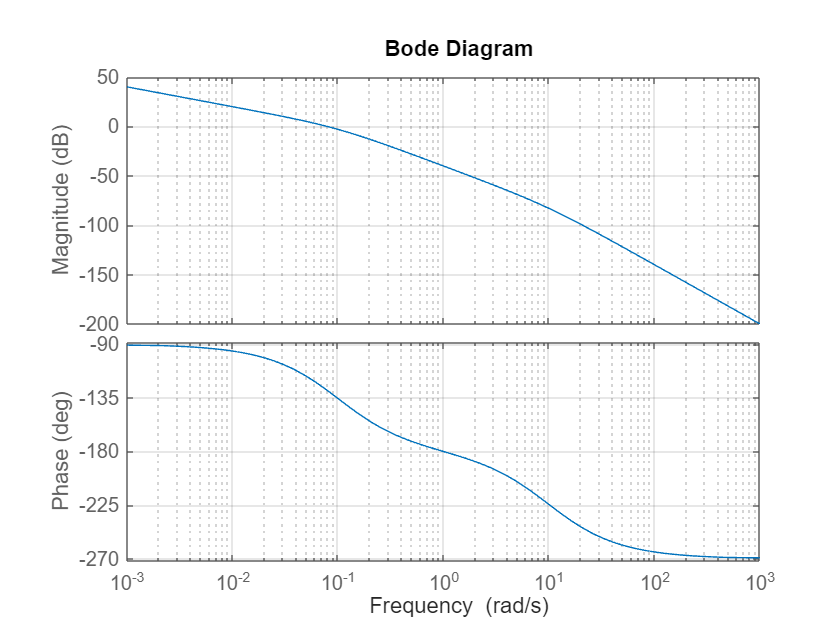

sys1 = tf([1],[10 101 10 0]);
bode(sys1);
grid on;

syms K
solve(3 == 20*log10(K))

$$ans = 10^{3/20}$$

var = vpa(ans)

$$var = 1.4125375446227543021556078639302$$

#### 3)

#### 4)

clear all
close
syms s
D = 1;
expr1 = 1/(10*s+1);
expr2 = 1/(0.1*s+1);
T = (D*expr1^2)/(1+(D*expr1^2*expr2));
sys1 = tf([1 10], [100 1020 201 20]);
b = [1 10];
a = [100 1020 201 20];
[z,p,k] = tf2zp(b,a)

z =    -10


p =           -10.0010200938193 +                     0i
         -0.099489953090354 +     0.100497309688059i
         -0.099489953090354 -     0.100497309688059i


k =                       0.01


collect(T,s);
Y = expr1/(1+((expr1^2)*(D)));
collect(Y,s);

#### 5)